clc; close all ; clear;
image_read = imread('C:\Users\Adham\Desktop\Mesho.jpg');

% encoding image into array of encoded_bits
image_gray = rgb2gray(image_read);
image_bits = reshape((dec2bin(typecast(image_gray(:) , 'uint8'), 8) - '0').', 1, []);
original_image_class = class(image_gray);
original_image_size = size(image_gray);

## Simulation with matlab built in functions

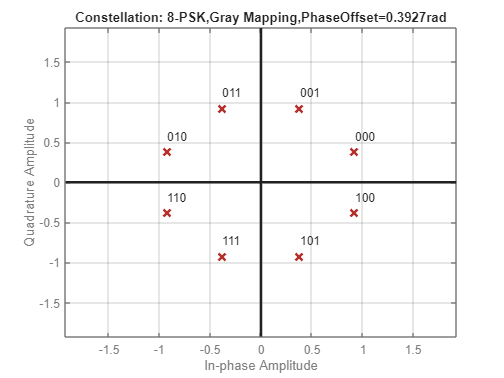

encoded_bits = image_bits;
pskModulator = comm.PSKModulator(8,'BitInput',true);
pskDemodulator = comm.PSKDemodulator(8,'BitOutput',true);
constellation(pskModulator)

modulated_signal = pskModulator(encoded_bits');
Demodulated_data = pskDemodulator(modulated_signal);
calc_ber(Demodulated_data,encoded_bits')

ans = 0

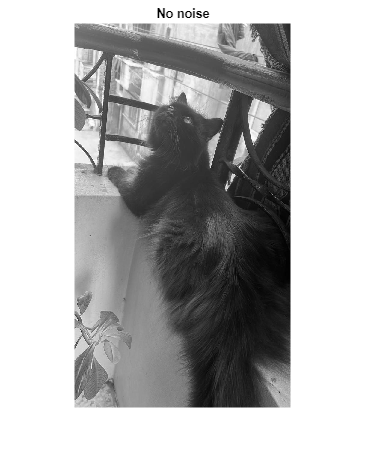

reconstructed = reshape(typecast(uint8(bin2dec(char(reshape(Demodulated_data, 8, [])+'0').')), original_image_class), original_image_size);
figure()
imshow(reconstructed)
title('No noise')

## Noisy AWGN

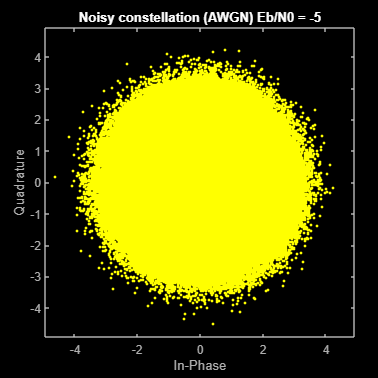

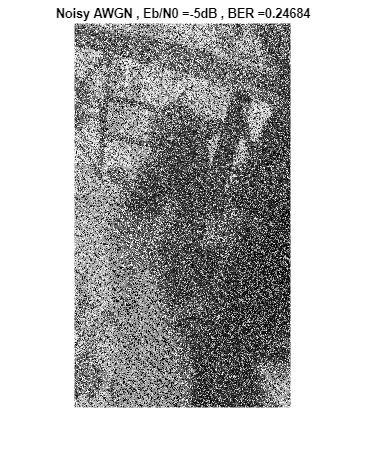

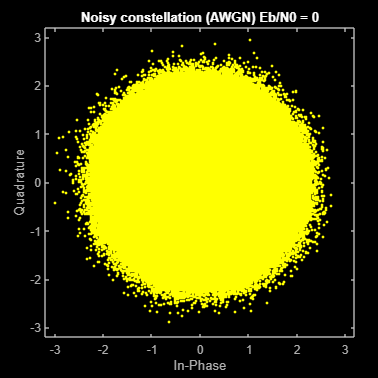

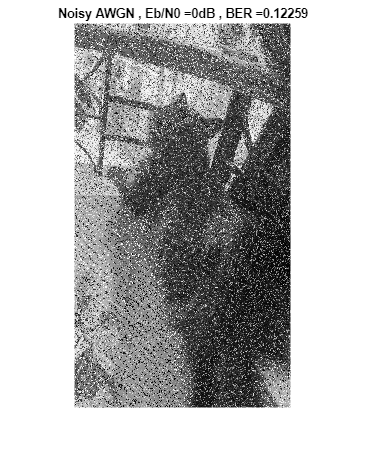

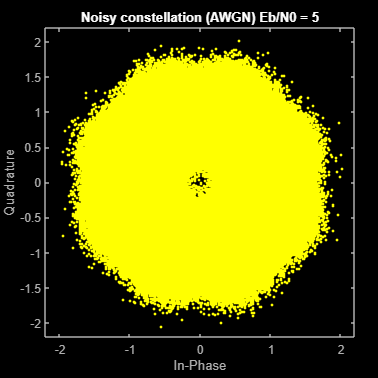

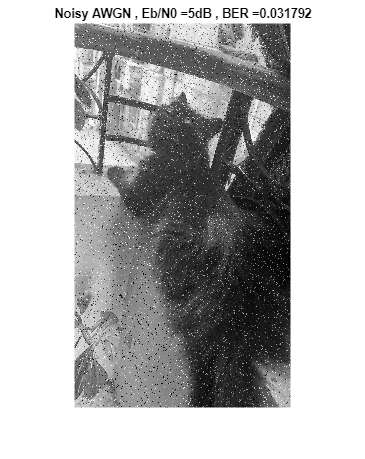

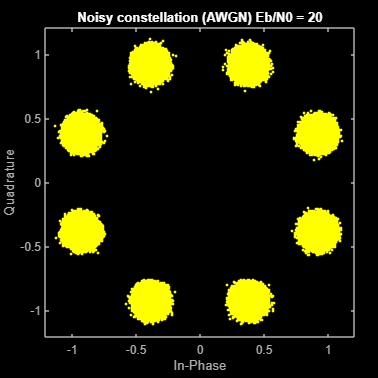

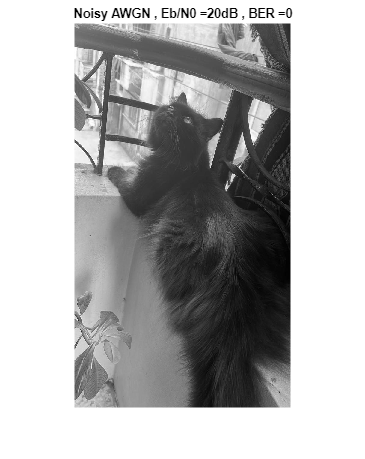

encoded_bits = image_bits;

Eb_N0s = [-5 0 5 20];
for Eb_N0 = Eb_N0s 
    pskModulator = comm.PSKModulator(8,'BitInput',true);
    pskDemodulator = comm.PSKDemodulator(8,'BitOutput',true);
    awgnChannel = comm.AWGNChannel('BitsPerSymbol',log2(8));
    awgnChannel.EbNo = Eb_N0;
    modulated_signal = pskModulator(encoded_bits');
    modulated_signal = awgnChannel(modulated_signal);
    Demodulated_data = pskDemodulator(modulated_signal);

    ber = calc_ber(Demodulated_data,encoded_bits');
    figure()
    scatterplot(modulated_signal)
    title("Noisy constellation (AWGN) Eb/N0 = " + num2str(Eb_N0))

    reconstructed = reshape(typecast(uint8(bin2dec(char(reshape(Demodulated_data, 8, [])+'0').')), original_image_class), original_image_size);
    
    figure()
    imshow(reconstructed)
    title("Noisy AWGN , Eb/N0 ="+ num2str(Eb_N0)+ "dB , BER =" + num2str(ber))
end

## Rician channel simulation

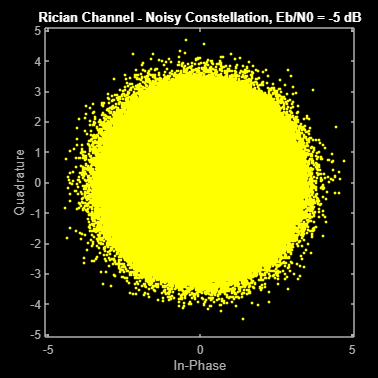

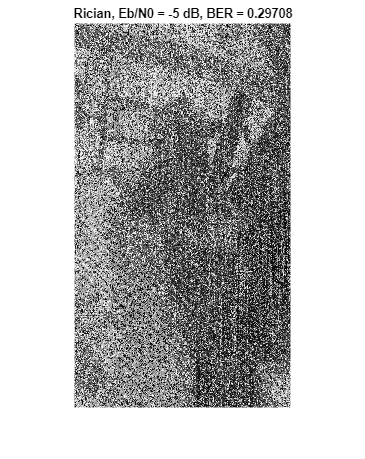

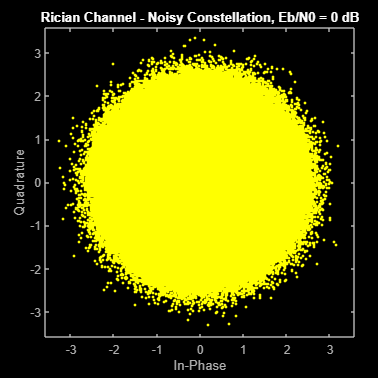

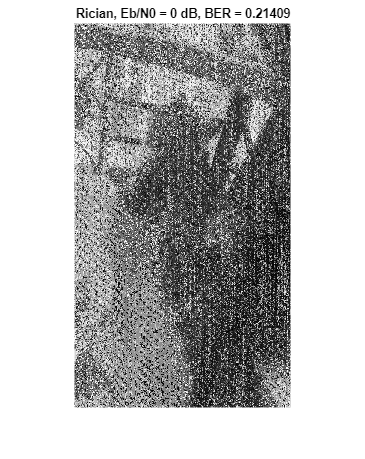

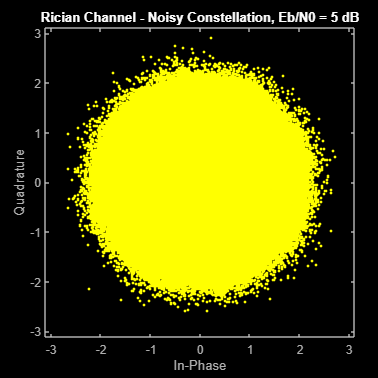

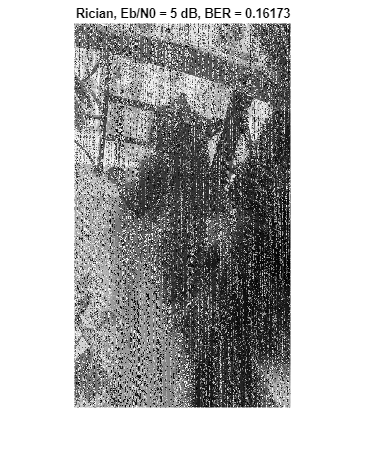

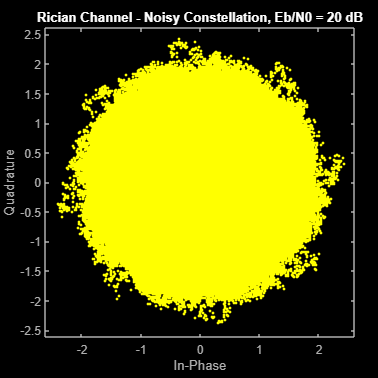

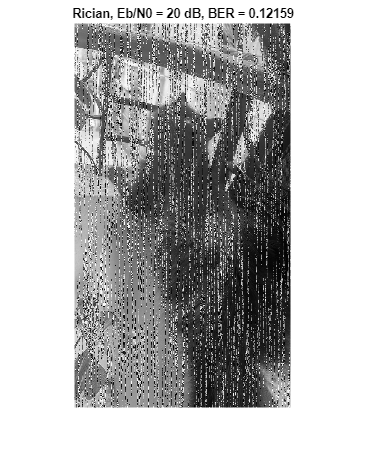

% Rician channel simulation
for Eb_N0 = Eb_N0s
    pskModulator = comm.PSKModulator(8, 'BitInput', true);
    pskDemodulator = comm.PSKDemodulator(8, 'BitOutput', true);
    ricianChannel = comm.RicianChannel();
    awgnChannel = comm.AWGNChannel('BitsPerSymbol', log2(8));
    awgnChannel.EbNo = Eb_N0;

    modulated_signal = pskModulator(image_bits');
    faded_signal = ricianChannel(modulated_signal);
    noisy_signal = awgnChannel(faded_signal);
    Demodulated_data = pskDemodulator(noisy_signal);

    ber = calc_ber(Demodulated_data, image_bits');
    
    % Display constellation
    figure();
    scatterplot(noisy_signal);
    title("Rician Channel - Noisy Constellation, Eb/N0 = " + num2str(Eb_N0) + " dB");

    % Reconstruct and display the image
    reconstructed = reshape(typecast(uint8(bin2dec(char(reshape(Demodulated_data, 8, []) + '0').')), ...
                              original_image_class), original_image_size);
    figure();
    imshow(reconstructed);
    title("Rician, Eb/N0 = " + num2str(Eb_N0) + " dB, BER = " + num2str(ber));
end

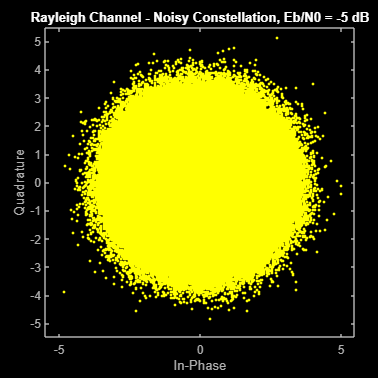

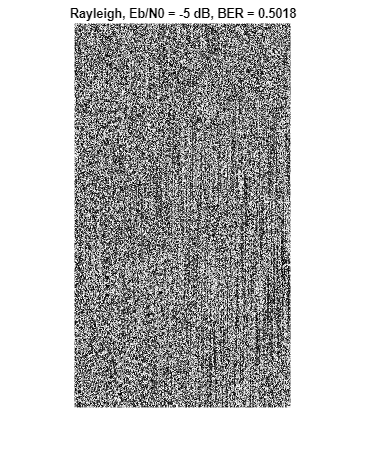

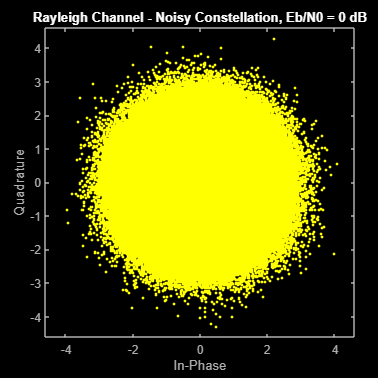

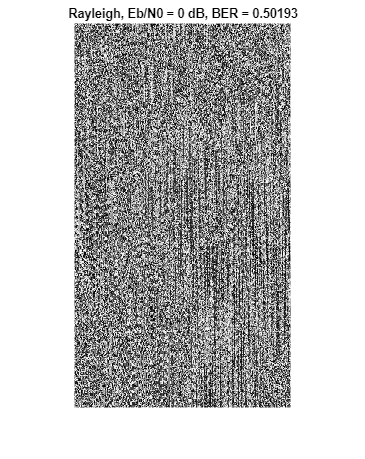

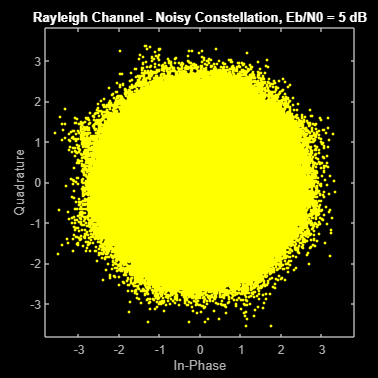

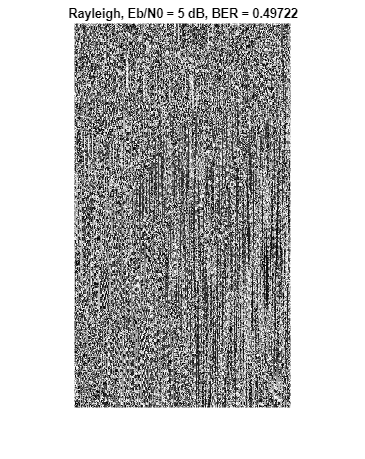

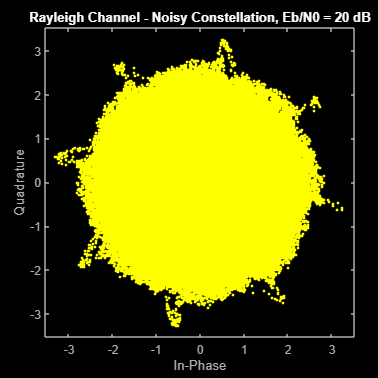

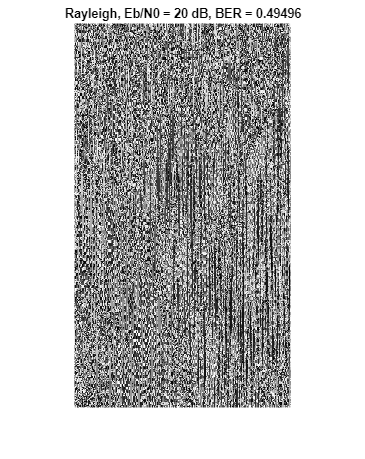


% Rayleigh channel simulation
for Eb_N0 = Eb_N0s
    pskModulator = comm.PSKModulator(8, 'BitInput', true);
    pskDemodulator = comm.PSKDemodulator(8, 'BitOutput', true);
    rayleighChannel = comm.RayleighChannel();
    awgnChannel = comm.AWGNChannel('BitsPerSymbol', log2(8));
    awgnChannel.EbNo = Eb_N0;

    modulated_signal = pskModulator(image_bits');
    faded_signal = rayleighChannel(modulated_signal);
    noisy_signal = awgnChannel(faded_signal);
    Demodulated_data = pskDemodulator(noisy_signal);

    ber = calc_ber(Demodulated_data, image_bits');
    
    % Display constellation
    figure();
    scatterplot(noisy_signal);
    title("Rayleigh Channel - Noisy Constellation, Eb/N0 = " + num2str(Eb_N0) + " dB");

    % Reconstruct and display the image
    reconstructed = reshape(typecast(uint8(bin2dec(char(reshape(Demodulated_data, 8, []) + '0').')), ...
                              original_image_class), original_image_size);
    figure();
    imshow(reconstructed);
    title("Rayleigh, Eb/N0 = " + num2str(Eb_N0) + " dB, BER = " + num2str(ber));
end

## BER figures

encoded_bits = image_bits(1 :1998);
eb_n0_vals = -15 :0.5 :15;
pskModulator = comm.PSKModulator(8,'BitInput',true);
pskDemodulator = comm.PSKDemodulator(8,'BitOutput',true);
awgnChannel = comm.AWGNChannel('BitsPerSymbol',log2(8));
bers = zeros(1 , length(eb_n0_vals));
for i = 1 : length(eb_n0_vals)
    eb_n0 = eb_n0_vals(i);
    for j = 1 : 50
    awgnChannel.EbNo = eb_n0;
    modulated_signal = pskModulator(encoded_bits');
    modulated_signal = awgnChannel(modulated_signal);
    Demodulated_data = pskDemodulator(modulated_signal);
    
    bers(i) = bers(i)+ calc_ber(Demodulated_data,encoded_bits');
    end
    bers(i) = bers(i) / 50;
end

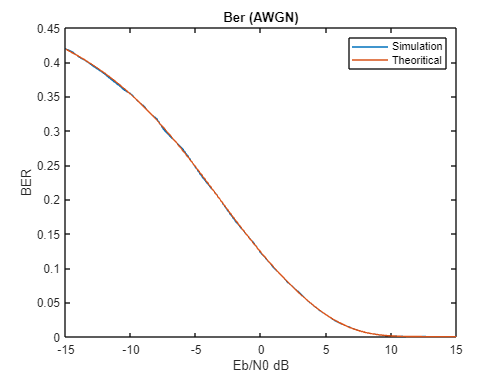

bers_t = berawgn(eb_n0_vals,'psk',8,'nondiff');
figure()
plot(eb_n0_vals,bers)
hold on
plot(eb_n0_vals,bers_t)
title('Ber (AWGN)')
xlabel('Eb/N0 dB')
ylabel('BER')
legend('Simulation','Theoritical')

Functions

function res = calc_ber(encoded_bits,rec)
     res = sum(encoded_bits ~= rec) / length(rec);
end